# 

## MATLAB Fundamentals: Tutorial 02, Exercise 06

### August 2023

# 6.  Moving Robot  

In this final exercise, you apply most of what you have learned so far to the problem of a moving robot, like the line-tracking robot considered in the scope of this lab course. Figure 6-1 shows the geometry of the robot. It has two wheels driven by one motor each, and a third, ball-shaped support. 

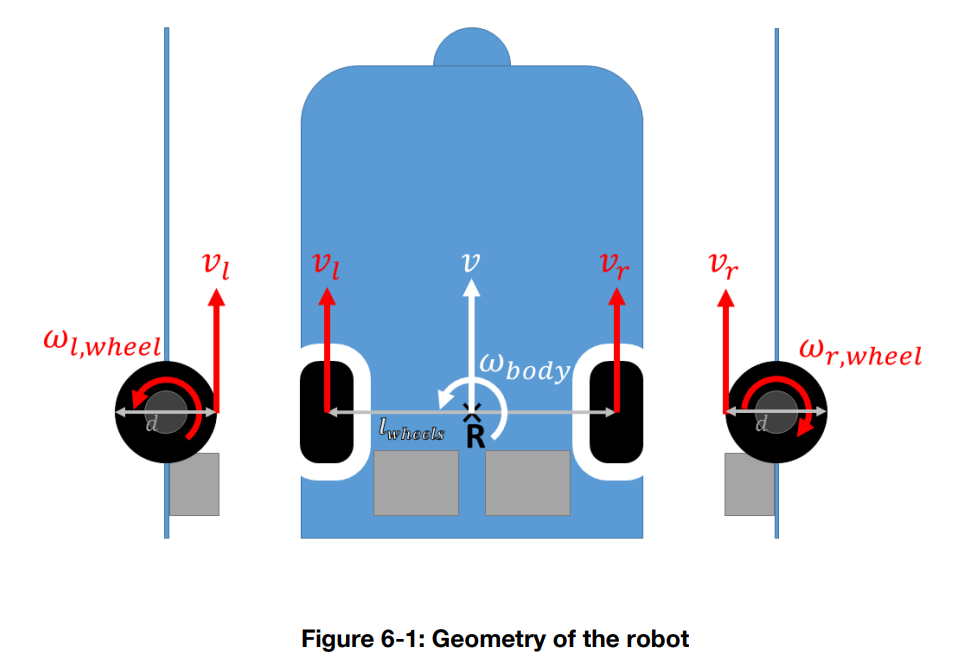

Consider the left and right wheel rotation rates $\omega_{lw}(t)$ and $\omega_{rw}(t)$ given. Using the wheels diameter 𝑑, the linear wheel speed can be calculated:


$$\begin{array}{rcl}
v_r &=& \omega_{rw} \frac d2 \\
v_l &=& \omega_{lw} \frac d2 \\
\end{array}$$


The forward speed at the reference point can then be calculated as:


$$v = \frac 12 \left( v_r + v_l \right)$$


and the rotational rate of the robot is:


$$\omega = \frac {1} {l_\text{wheels}} (v_r - v_l)$$


Using these quantities, the nonlinear equations of motion of the robot can be stated as:


$$\begin{array}{rcl}
\dot \phi &=& \omega \\
\dot x&=& v\cos\phi \\
\dot y&=& v\sin\phi
\end{array}$$


**Exercise**

(1)     Convert the systems of equations in MATLAB symbolic language. Let $t$ be positive.

syms t phi(t) x(t) y(t) omega_lw(t) omega_rw(t) d l_wheels
v_r = omega_rw * d/2;
v_l = omega_lw * d/2;
v = (v_r+v_l)/2;
omega = (v_r-v_l)/l_wheels;
phi_dot = diff(phi,t) == omega;
x_dot = diff(x,t) == v*cos(phi);
y_dot = diff(y,t) == v*sin(phi);

(2)    Consider $\omega_{lw} = 8\sin^2t$ and $\omega_{rw} = 8\cos^2t$. What are the resulting robot speed $v^*$ and robot rotational rate $\omega^*$? (The star denotes this particular solution.) 

omega_lw = 8 * sin(t)^2;
omega_rw = 8 * sin(t)^2;
v_r = omega_rw * d/2;
v_l = omega_lw * d/2;
v_star = (v_r + v_l) / 2;
omega_star = (v_r - v_l) / l_wheels;
v_star = simplify(v_star);
omega_star = simplify(omega_star);

(3)    When is the first moment $t > 0$ at which the robot does not rotate (i.e. $\omega^* = 0$)? Assume $d = 0.03\text m$ and $l_{wheels} = 0.1\text m$. Give a 3-digit approximation. What happens if you do not specify the interval in which you are looking for the solution? What can you deduce regarding this function's behavior with assumptions?

% Define symbolic variable for time
syms t

% Given parameters
d = 0.03;           % diameter of the wheels in meters
l_wheels = 0.1;     % distance between wheels in meters

% Define left and right wheel rotation rates
omega_lw = 8 * sin(t)^2;
omega_rw = 8 * cos(t)^2;

% Calculate linear wheel speeds
vr = omega_rw * d / 2;
vl = omega_lw * d / 2;

% Calculate the rotational rate omega*
omega_star = (vr - vl) / l_wheels;

% Solve for t when omega* = 0
t_solution = vpasolve(omega_star == 0, t, [0 Inf]);

% Display the solution with 3-digit approximation
disp('First moment t > 0 at which the robot does not rotate:');

First moment t > 0 at which the robot does not rotate:


disp(vpa(t_solution, 3));

$$21.2$$

### *Hint:* Make a first guess based on a symbolic plot, then determine the result by numeric equation solving, using `vpasolve`.

(4)    Determine the robot’s position after 50 seconds, $x(50\text s)$ and $y(50\text s)$.

% Define symbolic variables
syms t x(t) y(t) phi(t) d l_wheels

% Define the left and right wheel rotation rates
omega_lw = 8 * sin(t)^2;
omega_rw = 8 * cos(t)^2;

% Define linear wheel speeds based on the given wheel diameter d
d = 0.03; % in meters
vr = omega_rw * d / 2;
vl = omega_lw * d / 2;

% Define the forward speed v and rotational rate omega
v = (vr + vl) / 2;
omega = (vr - vl) / l_wheels;

% Solve for phi(t) by integrating omega with respect to time
phi_sol = int(omega, t);

% Define the differential equations for x(t) and y(t)
x_dot = v * cos(phi_sol);
y_dot = v * sin(phi_sol);

% Integrate x_dot and y_dot to find x(t) and y(t)
x_sol = int(x_dot, t);
y_sol = int(y_dot, t);

% Substitute t = 50 seconds into x(t) and y(t)
x_50 = subs(x_sol, t, 50);
y_50 = subs(y_sol, t, 50);

% Display the results
disp('Position x(50s):');

Position x(50s):


disp(vpa(x_50, 5)); % Display with 5-digit precision

$${\int \cos\left(\frac{3\,\sin\left(2\,t\right)}{50\,l_{\mathrm{wheels}}}\right)\,\left(\frac{3\,{\cos\left(t\right)}^{2}}{50}+\frac{3\,{\sin\left(t\right)}^{2}}{50}\right)\mathrm{d}t|}_{t=50}$$

disp('Position y(50s):');

Position y(50s):


disp(vpa(y_50, 5)); % Display with 5-digit precision

$${\int \sin\left(\frac{3\,\sin\left(2\,t\right)}{50\,l_{\mathrm{wheels}}}\right)\,\left(\frac{3\,{\cos\left(t\right)}^{2}}{50}+\frac{3\,{\sin\left(t\right)}^{2}}{50}\right)\mathrm{d}t|}_{t=50}$$

### *Hint: *Make the right choice between definite and indefinite integration.

Technische Universität München – Lehrstuhl für Flugsystemdynamik – MATLAB Fundamentals: Tutorial 02 – August 2023